clear; clc
syms x h
syms u [1 2]
syms a [2 2]
syms b [1 3]

q=[1; x];
q1(x) = x^0;
q2(x) = x;
p = {q1 q2};

dq=diff(q);
t = [0 1 2];
h=1;
r = [0 h];


Weak derivative

eq = @(i,j) int(q(j)*a(i,:)*q,x,r) == -int(u(i)*diff(q(j),x),x,r) + ...
    b(i+1)*p{j}(r(2))-b(i)*p{j}(r(1));

sys = [ eq(1,1); eq(1,2); eq(2,1); eq(2,2) ]

$$sys = \left(\begin{array}{c} \frac{a_{1,2}}{2}+a_{1,1}=b_{2}-b_{1}\\ \frac{a_{1,2}}{3}+\frac{a_{1,1}}{2}=b_{2}-u_{1}\\ \frac{a_{2,2}}{2}+a_{2,1}=b_{3}-b_{2}\\ \frac{a_{2,2}}{3}+\frac{a_{2,1}}{2}=b_{3}-u_{2} \end{array}\right)$$

sol = solve(sys,a);
a=subs(a,sol);
a = subs(a,[b1 b3],[0 0])

$$a = \left(\begin{array}{cc} -2\,b_{2}+6\,u_{1} & 6\,b_{2}-12\,u_{1}\\ -4\,b_{2}+6\,u_{2} & 6\,b_{2}-12\,u_{2} \end{array}\right)$$


w=a*q

$$w = \left(\begin{array}{c} 6\,u_{1}-2\,b_{2}+x\,\left(6\,b_{2}-12\,u_{1}\right)\\ 6\,u_{2}-4\,b_{2}+x\,\left(6\,b_{2}-12\,u_{2}\right) \end{array}\right)$$

Stiffness matrix

s1 = [1,0,0]; 
v1=subs(w,[b2,u1,u2],s1)

$$v1 = \left(\begin{array}{c} -2+6\,x\\ -4+6\,x \end{array}\right)$$

s2 = [0,1,0];
v2=subs(w,[b2,u1,u2],s2)

$$v2 = \left(\begin{array}{c} 6-12\,x\\ 0 \end{array}\right)$$

s3=[0,0,1];
v3=subs(w,[b2,u1,u2],s3)

$$v3 = \left(\begin{array}{c} 0\\ 6-12\,x \end{array}\right)$$


L = @(f,s) int(w(1)*f(1),x,r) + int(w(2)*f(2),x,r) == int(s(2),x,r) + int(s(3),x,r);
k = @(f,g) int(g(1)*f(1),x,r) + int(g(2)*f(2),x,r);
sys = [ L(v1,s1); L(v2,s2); L(v3,s3) ]

$$sys = \left(\begin{array}{c} 8\,b_{2}-6\,u_{2}-6\,u_{1}=0\\ -6\,b_{2}+12\,u_{1}=1\\ -6\,b_{2}+12\,u_{2}=1 \end{array}\right)$$

K = [ k(v1,v1) k(v1,v2) k(v1,v3)
      k(v2,v1) k(v2,v2) k(v2,v3)
      k(v3,v1) k(v3,v2) k(v3,v3) ]

$$K = \left(\begin{array}{ccc} 8 & -6 & -6\\ -6 & 12 & 0\\ -6 & 0 & 12 \end{array}\right)$$


solve(sys)

ans = struct with fields:
    b2: 1/2
    u1: 1/3
    u2: 1/3


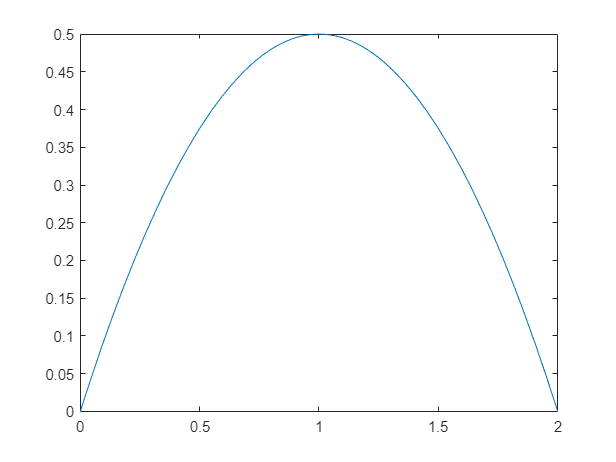


fplot((-x^2+2*x)/2,[0,2])